# Load the fingerprint

addpath ./predzpracovani
addpath ./porovnani
id = 3; num = 7;
im1 = loadfprint(id, num, 'fvc02_4');


% Custom fingerprints:
%im1 = double(imread("../my_fingerprints/f_1_13.bmp")) / 255;
%im1 = double(imread("../my_fingerprints/f_1_14.bmp")) / 255;
%im1 = double(imread("../my_fingerprints/f_1_15.bmp")) / 255;
%im1 = double(imread("../my_fingerprints/f_1_17.bmp")) / 255;

## Show orientation and frequency without segmentation

% Creatig imConotur (whole image)
[rows,cols] = size(im1);
imContour = zeros(rows, cols);
imContour(1, :) = 1;        % Top row
imContour(rows, :) = 1;     % Bottom row
imContour(:, 1) = 1;        % Leftmost column
imContour(:, cols) = 1;     % Rightmost column

% Creating imSegmented, where whole image is foreground
imSegmented = ones(rows,cols);

orientationArray = computeorientationarray(im1, imSegmented, 30);
%show_orientation(im1, imContour, imSegmented, orientationArray);
%saveas(gcf,'NoSegmentationOrientation.svg')

frequencyArray = computelocalfrequency(im1, imSegmented, orientationArray, false);
%show_frequency(im1, frequencyArray)
%saveas(gcf,'NoSegmentationFrequency.svg')

[imReconstruct imBinary imSkeleton] = enhance2ridgevalley(im1, imSegmented, orientationArray, frequencyArray, 0);
%show_gabor(imReconstruct, imSkeleton); % vykresleni
%saveas(gcf,'NoSegmentationGabor.svg')

## Segmentation from background

For segmentation fingerprint from background I chose method based on variance thresholding. I compute variance of block blkSize*blkSize and threshhold it.

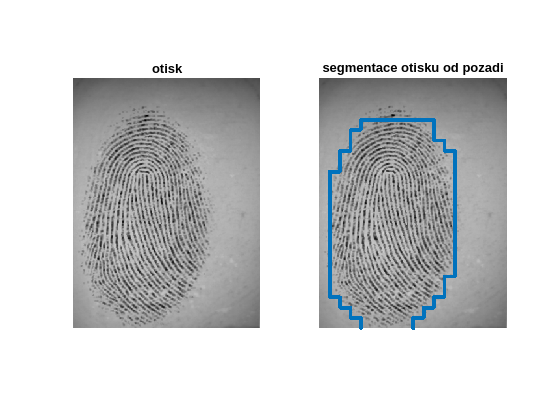

% Default values if segmentimage(im1)
thresh = 1e-3;
blkSize = 16;

[imSegmented imContour] = segmentimage(im1);
show_segmentation(im1, imContour);


%imshow(im1); hold on
%    [xc, yc]= find(imContour);
%    plot(yc, xc, '.');
%saveas(gcf,'Segmentation.svg')



## Compute orientation and frequency

orientationArray = computeorientationarray(im1, imSegmented, 30);
%show_orientation(im1, imContour, imSegmented, orientationArray);
%saveas(gcf,'SegmentationOrientation.svg')

frequencyArray = computelocalfrequency(im1, imSegmented, orientationArray, false);
%show_frequency(im1, frequencyArray)
%saveas(gcf,'SegmentationFrequency.svg')


## **Vylepseni kresby pomoci Gaborovych filtru + tvorba skeletonu**

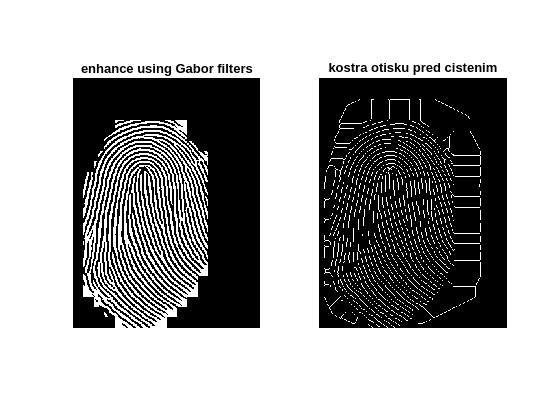

[imReconstruct imBinary imSkeleton] = enhance2ridgevalley(im1, imSegmented, orientationArray, frequencyArray, 0);
show_gabor(imReconstruct, imSkeleton); % vykresleni
saveas(gcf,'SegmentationGabor.svg')

## **Vycisteni skeletonu + finalni minutia**

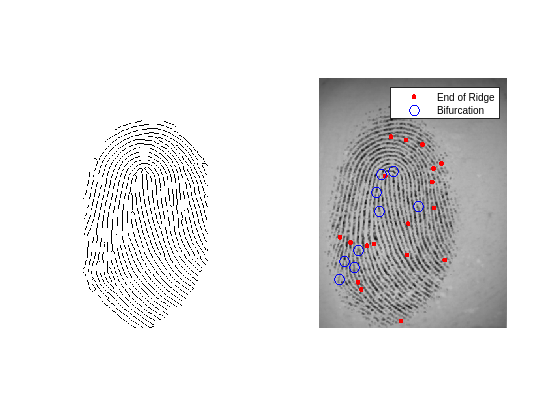

[imSkeleton minutiaArray] = cleanskeleton(im1, imSegmented, imContour, imSkeleton, orientationArray);
[minArray minRot] = findminutia(imSkeleton, imContour, orientationArray);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% vykresleni konecnych nalezenych minutii
show_minutia(im1, imSkeleton, minArray);
saveas(gcf,'SegmentationMinutia.svg')